clearvars
global options

Setting the range of settings and optimization parameters

Method          = ["sgdm","adam","rmsprop"];
initLearnRate   = [0.1 0.01 0.001];
MaxEpochs       = 150;  
MiniBatchSize   = [256 128];
Momentum        = 0.9;
conv            = 4;

Counter for experiment tracking

expNum = 1;

Loading training data through the matlab file responsible for it 

loadtrainingdata

setting the loops to run throught different options, if i just had one option i should comment the for loop for it and set the variable for it 

for lr = initLearnRate
    for mb = MiniBatchSize
        for mm = Method
            %for co = conv
            co = conv
            fprintf('\n=== Running Experiment %d ===\n', expNum);

clearing the variables that are more or less from previous expirments

            clearvars -except lr mb mm co conv ...
                options expNum ...
                trainImages valImages testImages ...
                trainLabels valLabels testLabels ...
                imageAugmenter trainDS valDS testDS ...
                initLearnRate MaxEpochs MiniBatchSize ...
                Momentum Method

calling the function that initialize the training options to loop through it

            createTrainingOptions(mm, lr,15, MaxEpochs, mb, valDS,50,Momentum,1)

selecting which set of layers will be applied to the network

            switch co
                case 2
                    conv2layers
                case 3
                    conv3layers
                case 4
                    conv4layers
            end

running the netweork 

co = 4


=== Running Experiment 1 ===


ans =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: 25
             ObjectiveMetricName: 


=== Running Training 1 ===

=== Done Training 1 ===


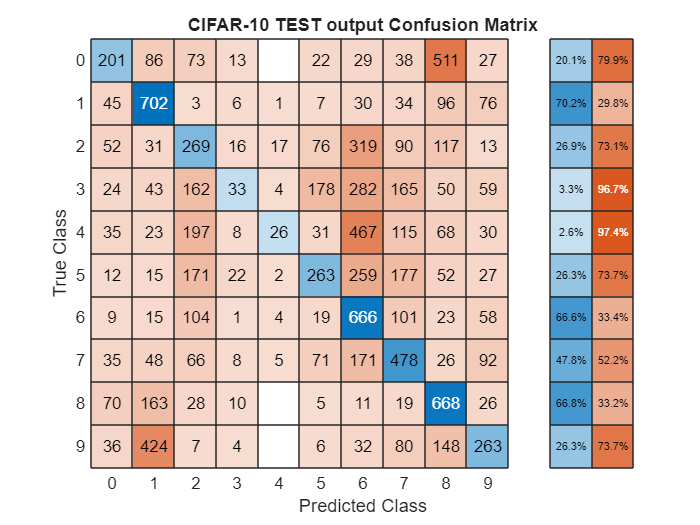

Overall Accuracy (from CM): 35.69%


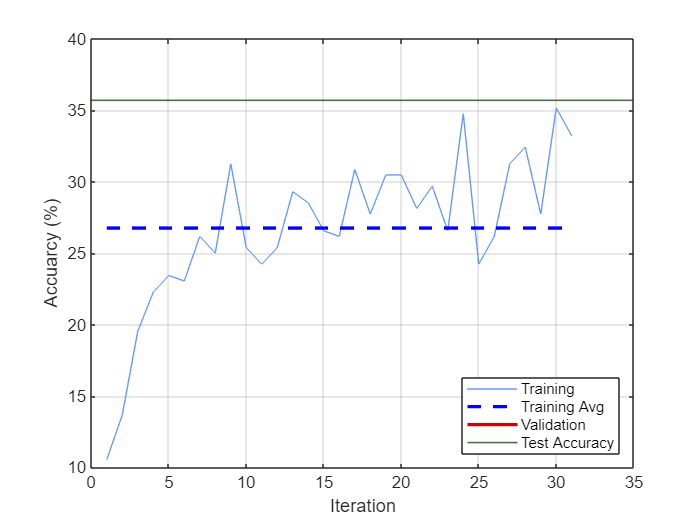

co = 4


=== Running Experiment 2 ===


ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.1000
                       MaxEpochs: 150
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 15
                   MiniBatchSize: 256
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-03
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Validatio


=== Running Training 2 ===


            runfile

            expNum = expNum + 1;
            %end
        end
    end
end